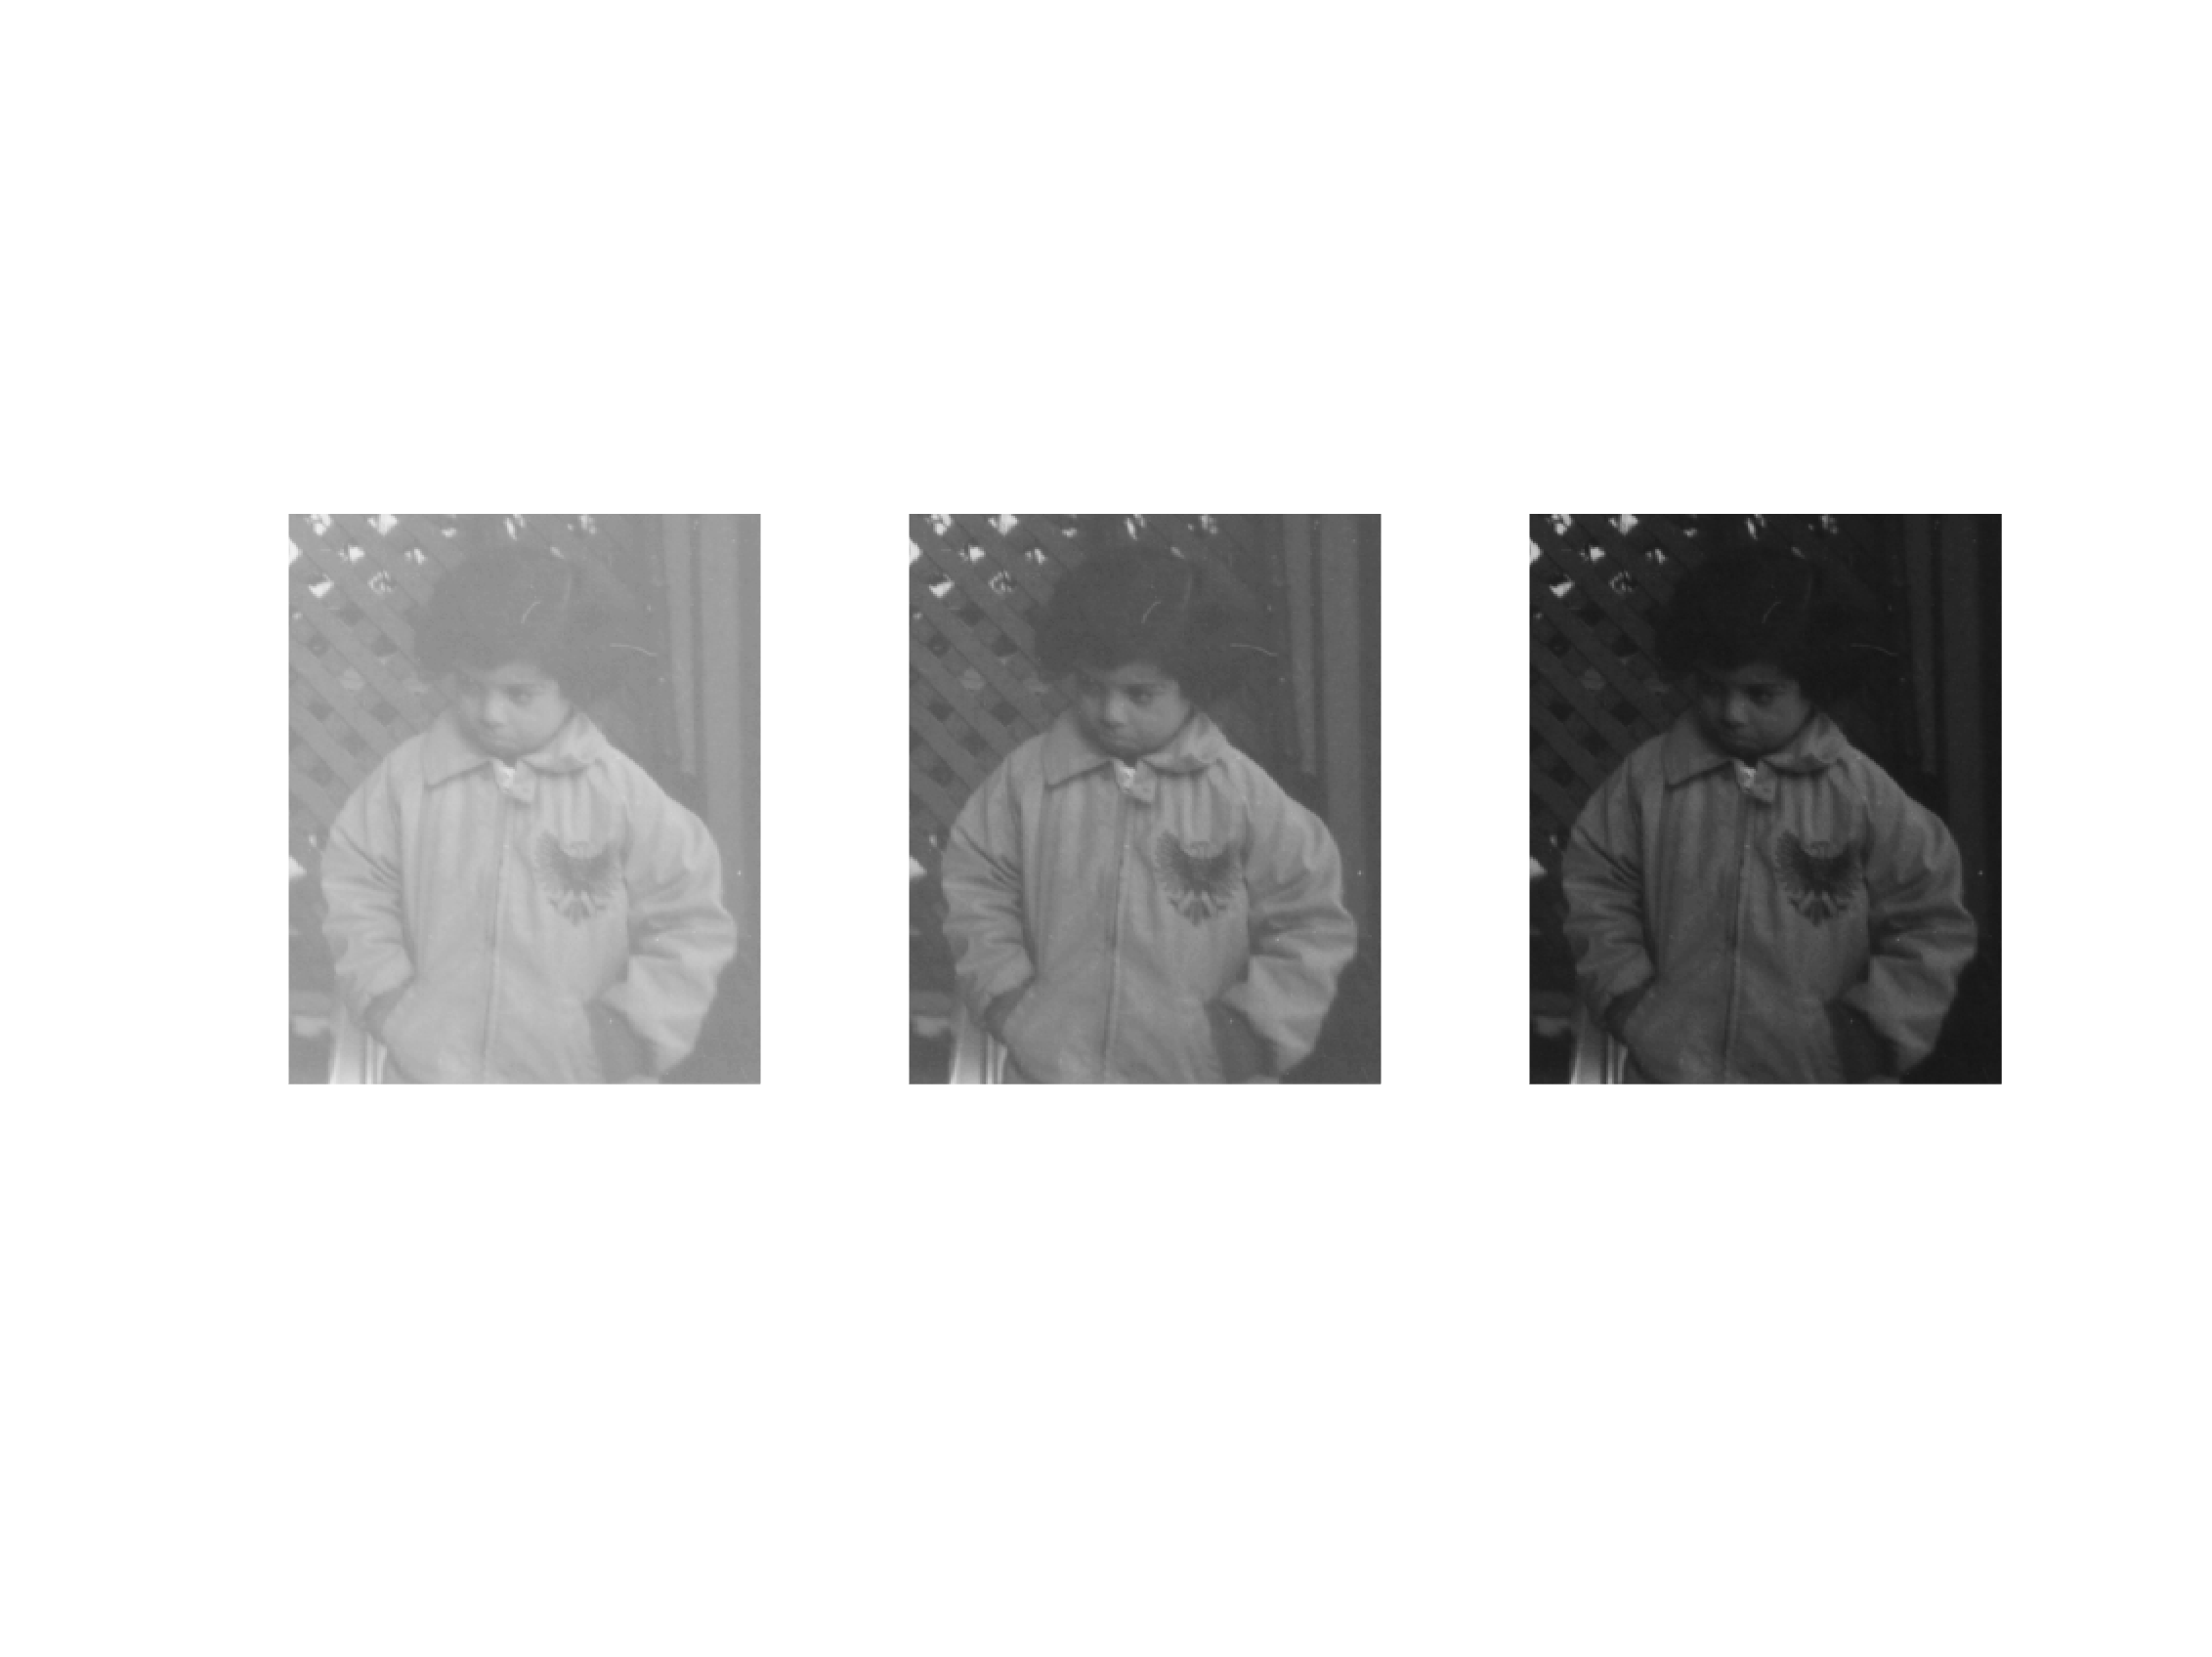


%% ECES 434 Assignment 1 – Live Script (Base MATLAB Version - No Toolboxes Required)

%% Setup: point MATLAB to the folder with your images
cd('/Users/abdullahk456/Library/CloudStorage/OneDrive-DrexelUniversity/Year4/Spring/ECE434/Assignment 1');

%% Part 1: Gamma Correction
pout = imread('pout.tif');
g05 = gamma_correction(pout, 0.5);
g10 = gamma_correction(pout, 1.0);
g20 = gamma_correction(pout, 2.0);
figure;
subplot(1,3,1), imshow(g05), title('\gamma = 0.5');
subplot(1,3,2), imshow(g10), title('\gamma = 1.0');
subplot(1,3,3), imshow(g20), title('\gamma = 2.0');

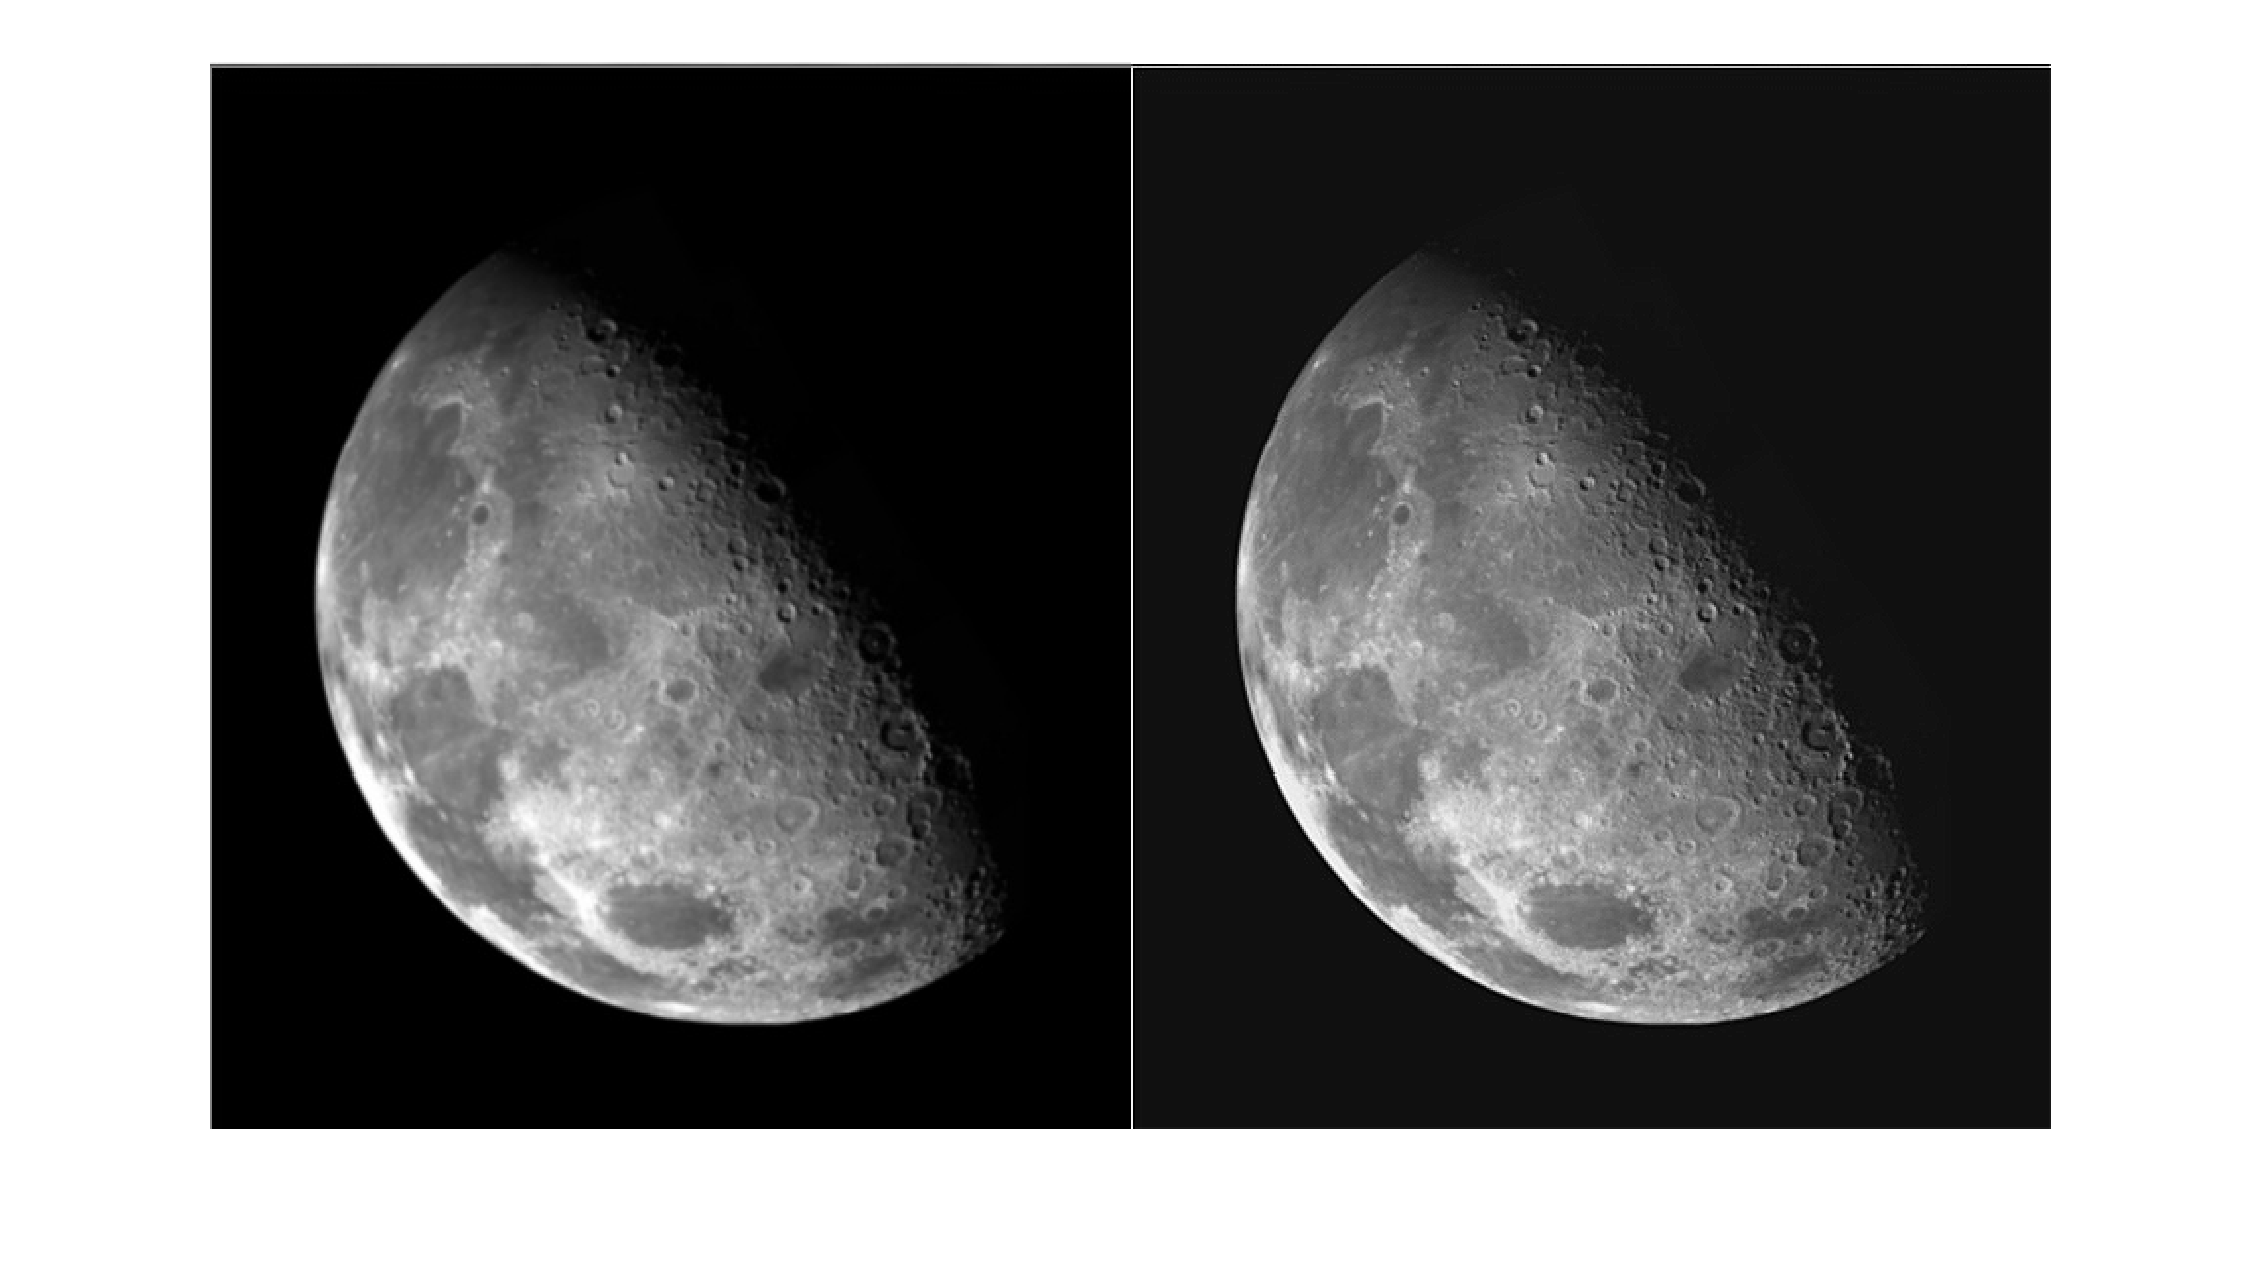


%% Part 2: High-Boost Filtering
moon = imread('moon.tiff');
hb2 = highboost_filter_base(moon, 2);
figure; imshowpair(moon, hb2, 'montage');

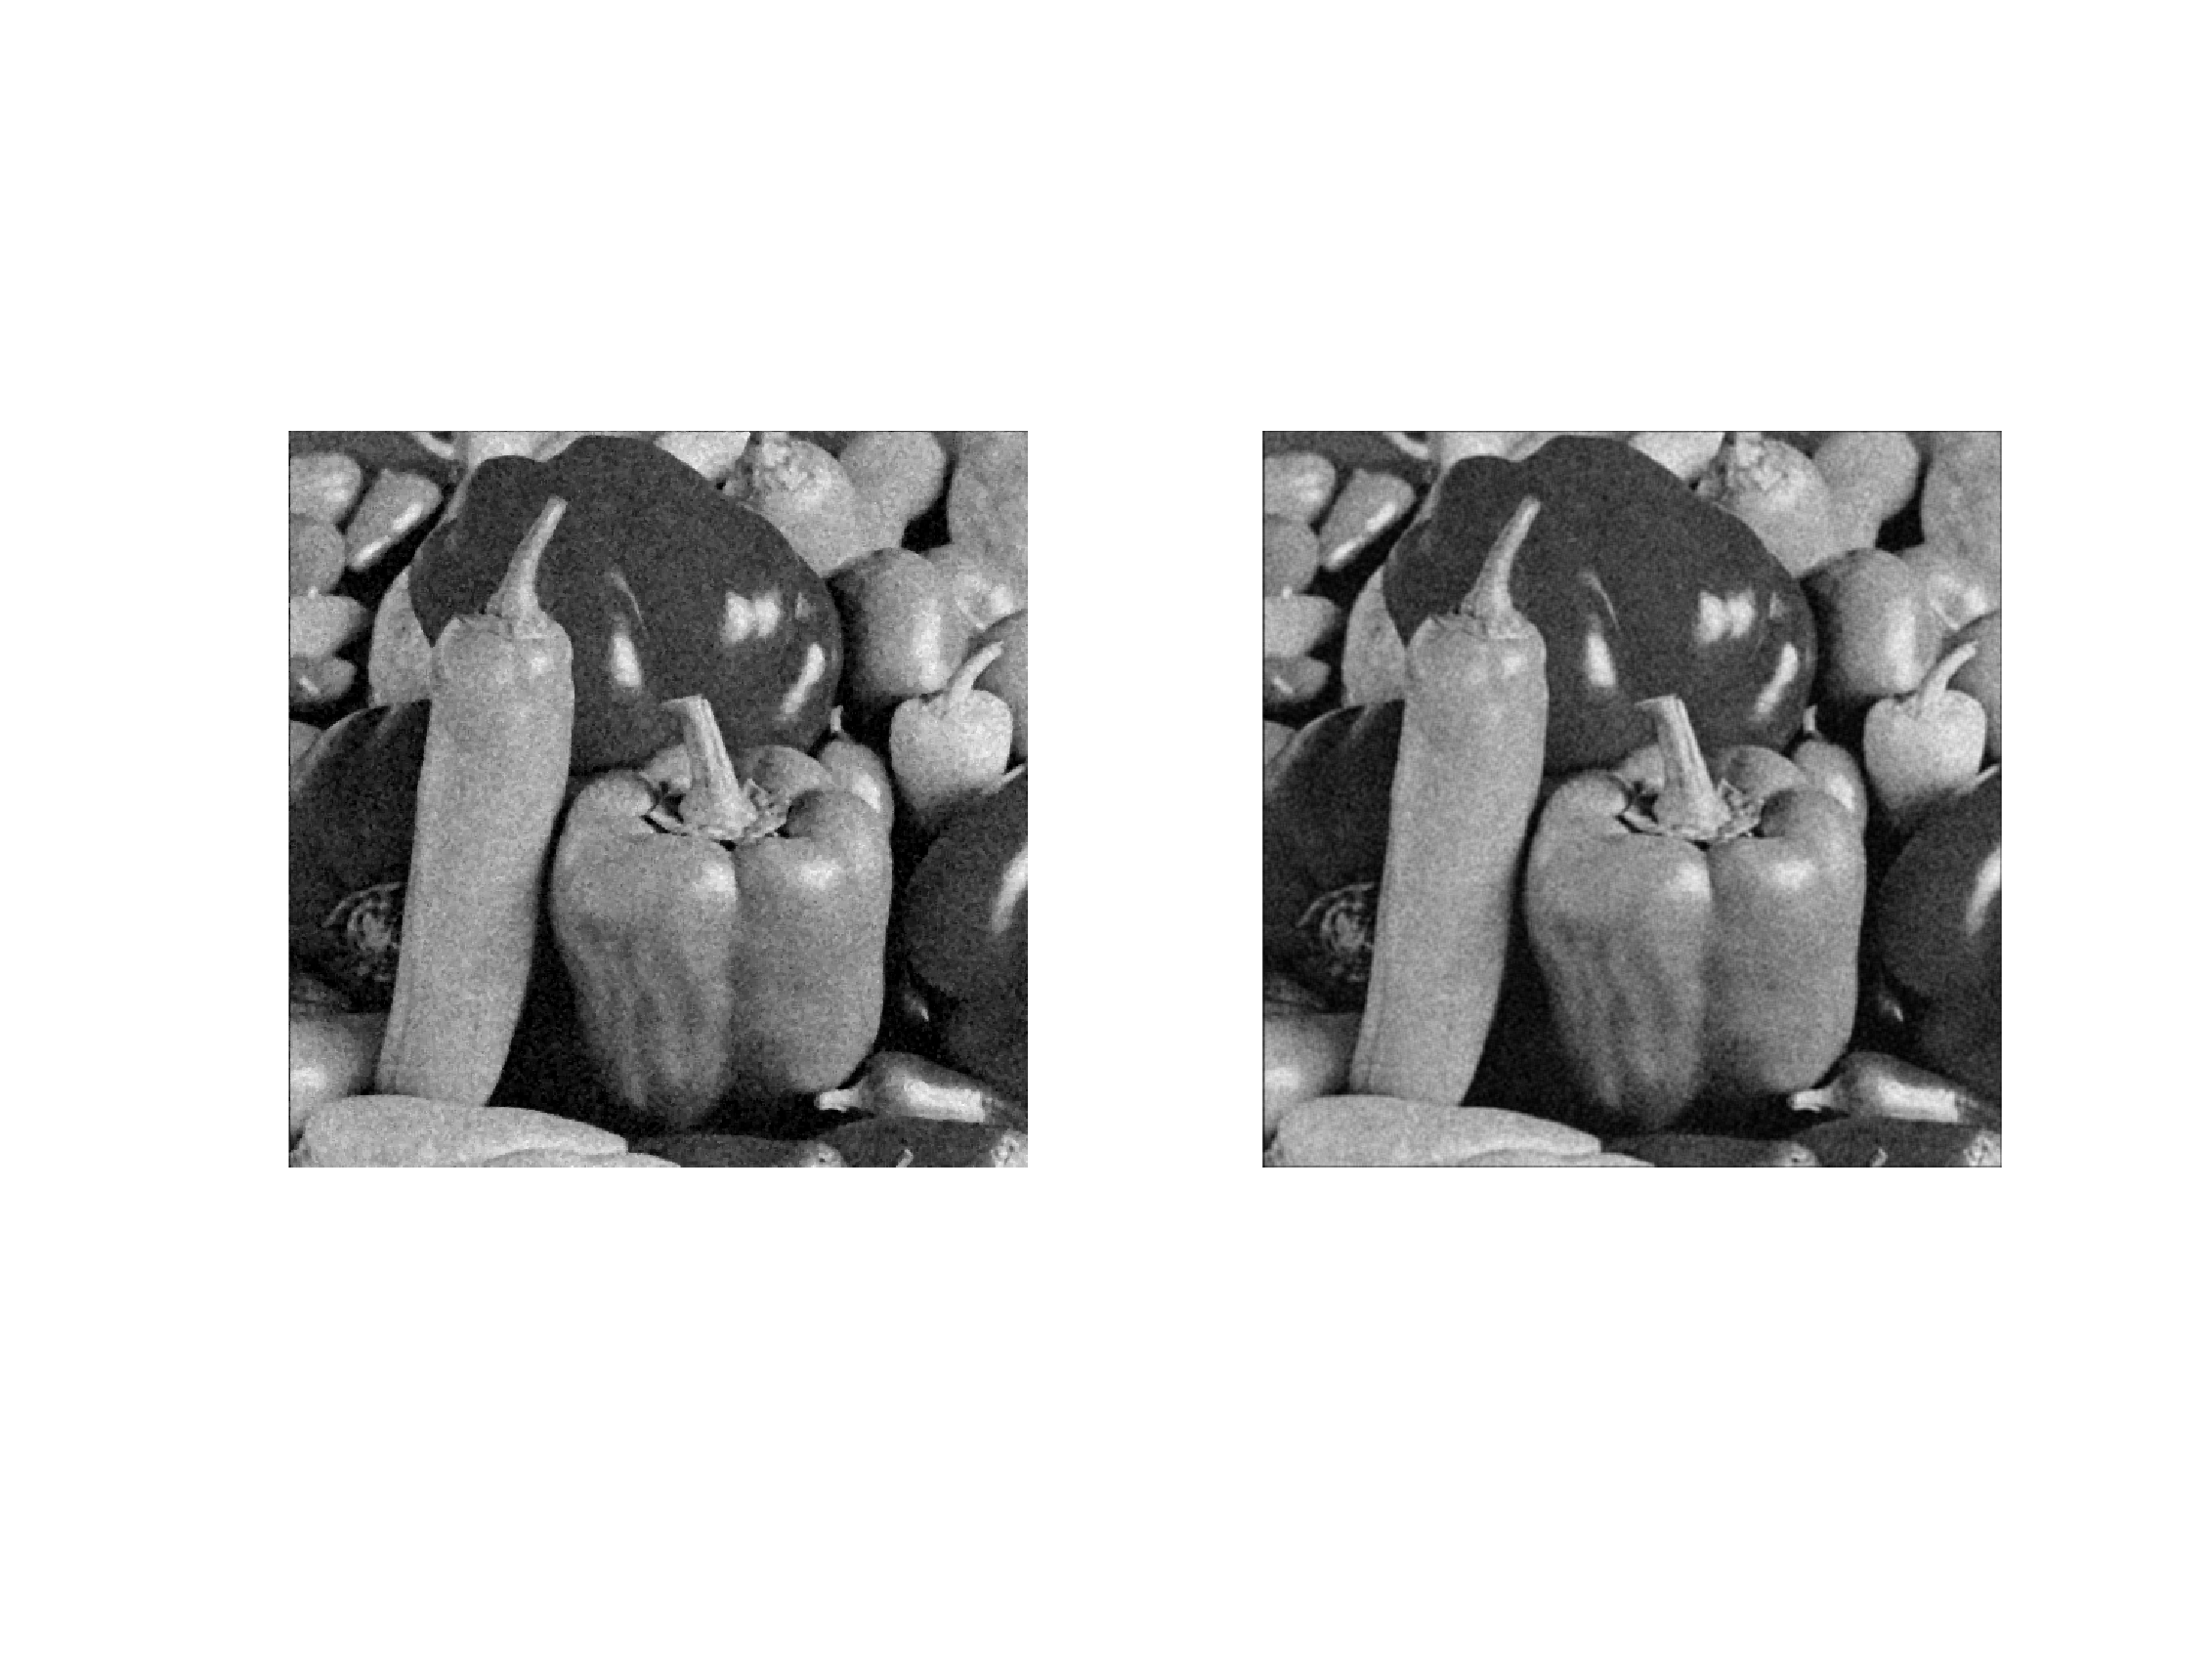


%% Part 3: Denoising & Edge Detection
noisy1 = imread('peppersNoise1.tiff');
avg3_1 = avg_filter_base(noisy1, 3);
med3_1 = median3x3_base(noisy1);

figure;
subplot(1,2,1), imshow(med3_1);
subplot(1,2,2), imshow(avg3_1);

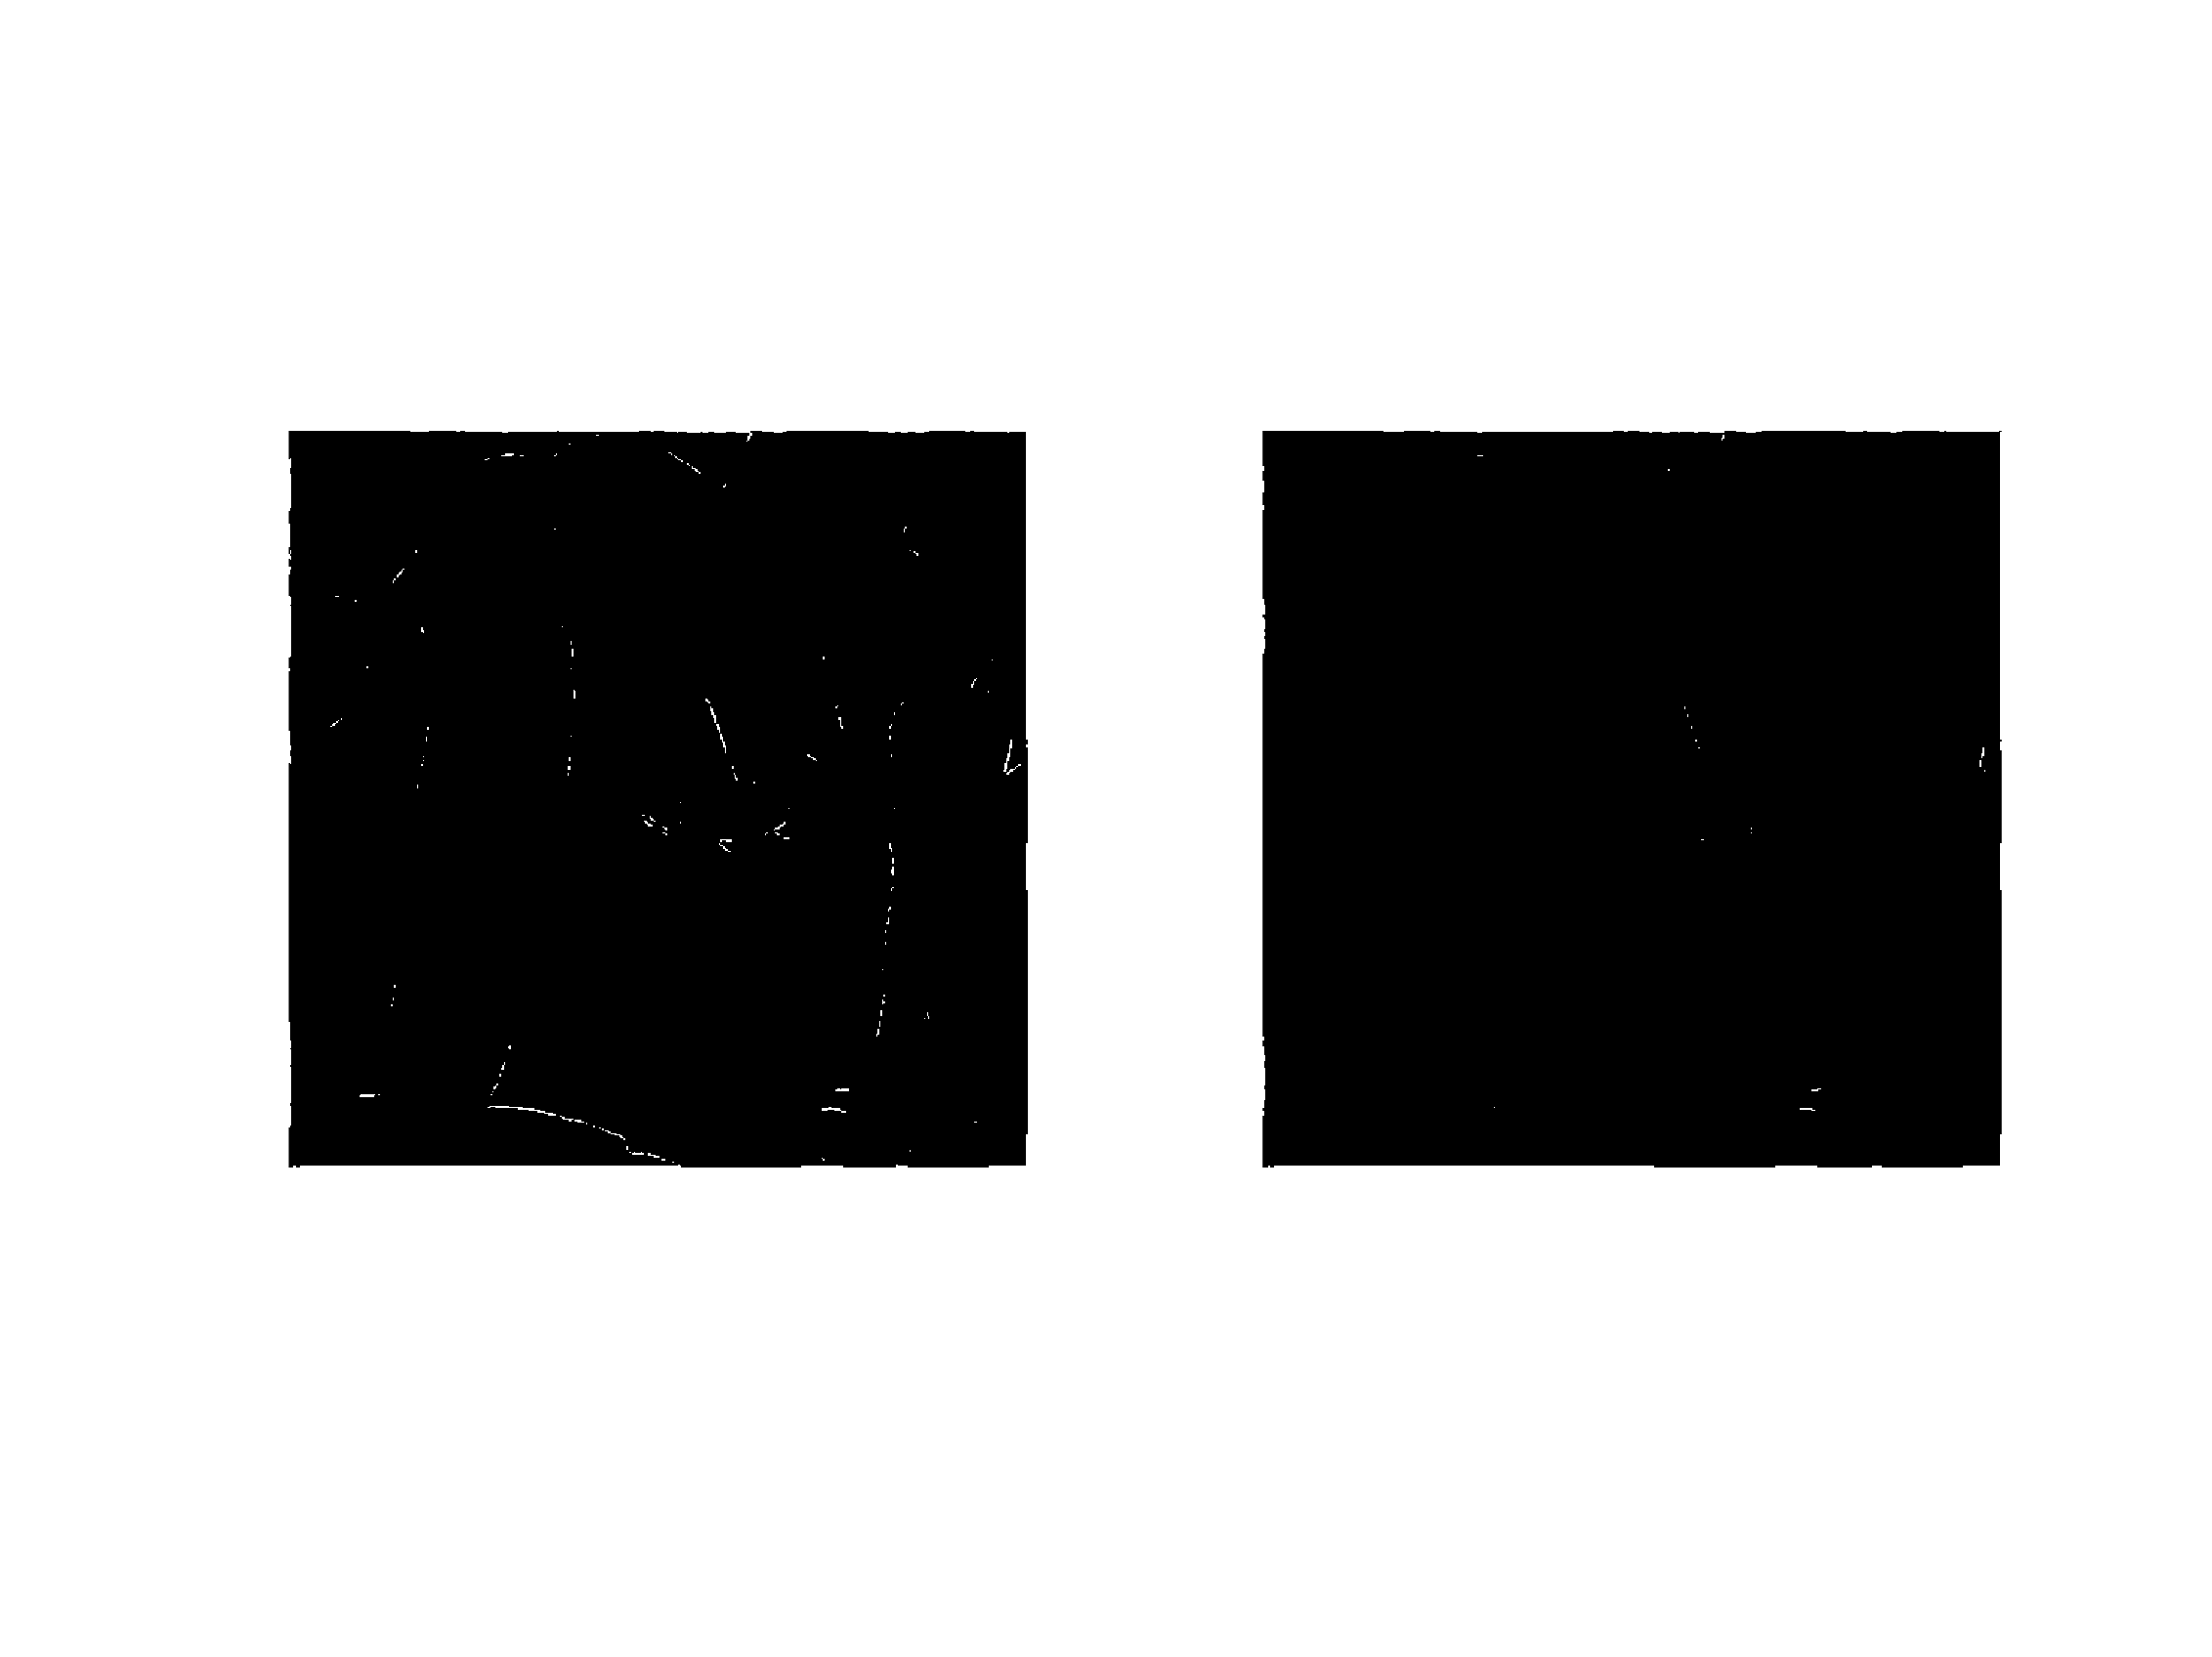


% Sobel Edge Detection (Base)
Sx = [-1 0 1; -2 0 2; -1 0 1];
Sy = Sx';
Gx_med = conv2(double(med3_1), Sx, 'same');
Gy_med = conv2(double(med3_1), Sy, 'same');
edgeMag_med = sqrt(Gx_med.^2 + Gy_med.^2);
edgeMap_med = edgeMag_med > graythresh(edgeMag_med)*max(edgeMag_med(:));

Gx_avg = conv2(double(avg3_1), Sx, 'same');
Gy_avg = conv2(double(avg3_1), Sy, 'same');
edgeMag_avg = sqrt(Gx_avg.^2 + Gy_avg.^2);
edgeMap_avg = edgeMag_avg > graythresh(edgeMag_avg)*max(edgeMag_avg(:));

figure;
subplot(1,2,1), imshow(edgeMap_med);
subplot(1,2,2), imshow(edgeMap_avg);


%% Local Functions

function out_img = gamma_correction(img, gamma)
    img_norm = double(img) / 255;
    img_gamma = img_norm .^ gamma;
    out_img = uint8(255 * img_gamma);
end

function out_img = highboost_filter_base(img, alpha)
    h = [0 -0.25 0; -0.25 1 -0.25; 0 -0.25 0];
    g = conv2(double(img), h, 'same');
    s = double(img) + alpha * g;
    s(s < 0) = 0;
    s(s > 255) = 255;
    out_img = uint8(s);
end

function out = avg_filter_base(img, m)
    kernel = ones(m) / m^2;
    tmp = conv2(double(img), kernel, 'same');
    out = uint8(tmp);
end

function out = median3x3_base(img)
    [r, c] = size(img);
    out = zeros(r, c, 'uint8');
    padded = uint8(zeros(r+2, c+2));
    padded(2:end-1, 2:end-1) = img;
    padded(1,2:end-1) = img(1,:);
    padded(end,2:end-1) = img(end,:);
    padded(:,1) = padded(:,2);
    padded(:,end) = padded(:,end-1);
    for i = 1:r
        for j = 1:c
            block = padded(i:i+2, j:j+2);
            out(i,j) = median(block(:));
        end
    end
end
